ans = 2.9957

sys =
 
              1
  --------------------------
  0.3333 s^2 + 0.1 s - 2.455
 
Continuous-time transfer function.



G =
 
       5.238 s^3 + 38.24 s^2 - 27.58 s - 270.1
  --------------------------------------------------
  0.1111 s^4 + 5.305 s^3 + 36.61 s^2 - 28.07 s - 264
 
Continuous-time transfer function.



p =   -39.2157
   -8.2272
    2.5680
   -2.8680


z =    -7.0000
    2.5680
   -2.8680


alpha = 0.5912

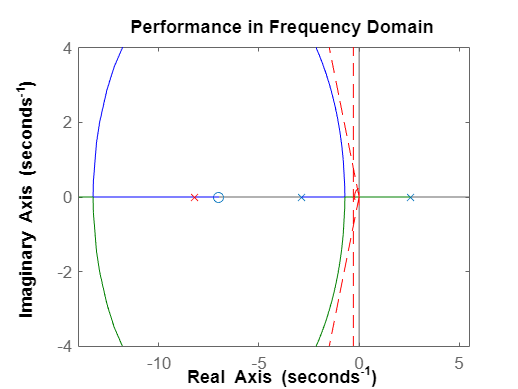

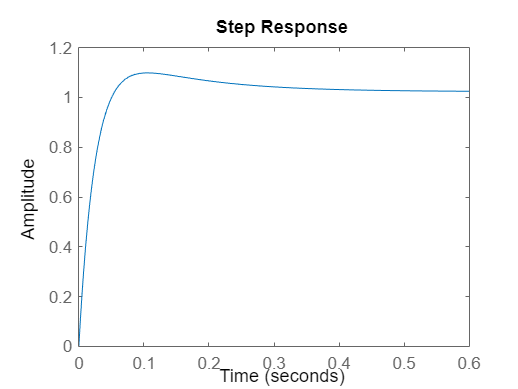

%L is the length
%angle is alpha
clc;

clear;
clf;

-log(5/100)

%%% tf shit %%%
s = tf('s');
sys = tf(1, [1/3 0.1 -2.455])
Ti = 1;
Td = 1/7;
N=2;
Kp = 110;
Kpi = 1 + 1/(Ti*s);
Kpd = 1 + Td*s;
%Kpid = 1 + 1/(Ti*s) + Td*s; 
Kpid = 1 + 1/(Ti*s) + (Td*s)/(1+s*Td/N);

rlocus(Kpd * sys)
hold on
K = Kp * Kpd;
G = (K * sys) / (1 + K * sys)
[p,z] = pzmap(G)
%po = [complex(p(2), 0) complex(p(5), 0) complex(p(6), 0)];
plot(p(1), 0, 'rx')
plot(p(2), 0, 'rx')

syms x2 y2 L alpha x y x3 tr ts sigma wn p1 p2 p3 p4
x = 0;
y= 0;
L = 40;
Mp = 10;
alpha = sqrt(((log(Mp/100)/-pi)^2)/(1+(log(Mp/100)/-pi)^2))

x2=-L*alpha;
y2=-L*cos(asin(alpha));
tr = 8;
wn = 1.8/tr;
ts = 16;
sigma = 4.6/ts; 
x3 = sigma;
zeta = 0.3495;

plot([0 5*(-zeta)], [0 5*cos(asin(-zeta))], '--', 'color', 'r')

plot([0 5*(-zeta)], [0 -5*cos(asin(-zeta))], '--', 'color', 'r')

plot([-x3 -x3],[-L/2 L/2], '--', 'color', 'r')

plot_arc(pi/2, 3*pi/2, 0,0, wn)
title('Performance in Frequency Domain','FontWeight','bold')
%legend('Overshoot1','Overshoot2', 'Settling time', 'Rise time');
xlabel('Real Axis','FontWeight','bold');
ylabel('Imaginary Axis','FontWeight','bold')
xlim([-14, 5.5])
ylim([-4, 4])

hold off

step(G)



function P = plot_arc(a,b,h,k,r)
    % Plot a circular arc as a pie wedge.
    % a is start of arc in radians, 
    % b is end of arc in radians, 
    % (h,k) is the center of the circle.
    % r is the radius.
    % Try this:   plot_arc(pi/4,3*pi/4,9,-4,3)
    % Author:  Matt Fig
    t = linspace(a,b);
    x = r*cos(t) + h;
    y = r*sin(t) + k;
    x = [x h x(1)];
    y = [y k y(1)];
    %P = fill(x,y,'r');
    P = plot(x,y, '--', 'color', 'r');
    %axis([h-r-1 h+r+1 k-r-1 k+r+1]) 
    if ~nargout
        clear P
    end
end
